# MXB201 Solutions 2

## Theory

General hint: sometimes in these proofs you will need to invoke one or both of the identities $(AB)^T = B^TA^T$ and $(AB)^{-1} = B^{-1}A^{-1}$ for invertible $A,B$.

T1.  Prove that the matrix $A^TA$ is symmetric for any $A$.


$$(A^TA)^T = A^T (A^T)^T = A^T A$$


T2.  Prove that $A^T A$ has the same null space as $A$.

Outline of proof:

Show that if $Ax = 0$ then $A^TA x = 0$.  Trivial.

$A^TAx = A^T(Ax) = A^T 0 = 0$.

Show that if $A^TAx = 0$ then $Ax = 0$.  Hint: take the dot product with $x$.

$0 = x \cdot 0 = x \cdot A^TAx = x^T A^TAx = (Ax)^T Ax = Ax \cdot Ax = \|Ax\|^2$.

So if $A^TAx  = 0$ then $\|Ax\| = 0$ which proves that $Ax = 0$.

T3.  Prove that if $A$ is of full column rank (i.e. $A$ has no linearly dependent columns) then $A^TA$ is invertible.

Proof:

If $\textrm{rank}(A) = n$ then $\textrm{nullity}(A) = 0$ since $\textrm{rank} + \textrm{nullity} = n$ (the rank-nullity theorem from Chapter 1)

But the null spaces of $A$ and $A^TA$ are the same (T2).

Hence $\textrm{nullity}(A^TA) = 0$.

Applying again $\textrm{rank} + \textrm{nullity} = n$, we see that $\textrm{rank}(A^TA) = n$.  Hence $A^TA$ is square and full rank, so invertible.

T4.  Let $P = A(A^T A)^{-1} A^T$ where $A$ is of full column rank.  Prove that:

(i) $P$ is symmetric.

Proof:

$P^T = [A(A^T A)^{-1} A^T]^T = (A^T)^T [(A^T A)^{-1}]^T A^T = A  [(A^T A)^T]^{-1} A = A (A^T A)^{-1} A$.

Note that we used the fact that tranpose and inverse commute: $(A^{-1})^T = (A^T)^{-1}$ for any $A$.  Sometimes we just write $A^{-T}$ !

(ii) $P$ is idempotent (satisfies $P^2 = P$).

Proof:

$P^2 = P P = A(A^T A)^{-1} A^T A(A^T A)^{-1} A^T = A(A^T A)^{-1} A^T = P$.

(iii) For a vector $b$ in the column space of $A$, $Pb = b$.

Proof:

If $b \in \textrm{colspace}(A)$ then $b = Ac$ for some vector $c$.

Then $Pb =  A(A^T A)^{-1} A^T Ac = Ac = b$.

(iv) For a vector $b$ orthogonal to the column space of $A$, $Pb = 0$.

Proof:

If $b \perp \textrm{colspace}(A)$ then $b \in \textrm{nullspace}(A^T)$.  That is, $A^T b = 0$.

Then $Pb =  A(A^T A)^{-1} A^T b = A(A^T A)^{-1} 0 = 0$.

(v) If $A$ is square and invertible, then $P = I$.  Geometrically what is this saying?

Proof:

If $A$ is square and invertible, then so is $A^T$.  And $(A^TA)^{-1} = A^{-1} A^{-T}$.

So $P =  A(A^T A)^{-1} A^T = A A^{-1} A^{-T} A^T = I$.

The columns of $A$ span $\mathbb{R}^n$ so projection onto $\textrm{colspace}(A)$ is just projection onto $\mathbb{R}^n$ itself.  So it leaves every vector unchanged: it's the identity operator.

(vi) $QP = 0$ where $Q = I-P$.  Geometrically what is this saying?

Proof:

$QP = (I-P)P = P - P^2 = P - P = 0$.

$QPb$ means project $b$ first onto the column space of $A$, and then project that result onto the orthogonal complement, the left null space.  But any vector in the column space has no component in the left null space, so this second projection is zero.

T5.  Prove that any matrix $P$ satisfying $P^2 = P$ and $P^T = P$ is an orthogonal projector.

Hint: what space would it project onto?  What condition would prove that this projection was orthogonal?

Proof:

For any vector $b$, $Pb$ lies in the column space of $P$ (by definition).  Hence $P$ projects onto its own column space: it could do nothing else!

For this projection to be orthogonal, it must be that for any vector $b$, the residual vector $b - Pb$ is orthogonal to the column space.

Now every vector in the column space is of the form $Pc$ for some vector $c$.

So we need to show that $(b - Pb) \cdot Pc = 0$ for all vectors $b$ and $c$.

$(b - Pb) \cdot Pc = (b - Pb)^T Pc = (b^T - b^T P^T) Pc = b^T(I - P^T) Pc = b^T(P - P^TP) c = b^T(P - P^2) c = b^T(P - P) c = 0$.

## Practice

P1.  Find the general solution to the least squares problem $x = \textrm{argmin}_{x^* \in \mathbb{R}^n} \|b - Ax^*\|$ for the following matrix $A$ and right hand side $b$.  This is the matrix `A_i` from Exercises 1.

A = sym([3 1 -3 ; 3 2 0 ; 2 1 -1]), b = sym([4;7;11])

$$A = \left(\begin{array}{ccc} 3 & 1 & -3\\ 3 & 2 & 0\\ 2 & 1 & -1 \end{array}\right)$$

$$b = \left(\begin{array}{c} 4\\ 7\\ 11 \end{array}\right)$$

ATA = A'*A, ATb = A'*b

$$ATA = \left(\begin{array}{ccc} 22 & 11 & -11\\ 11 & 6 & -4\\ -11 & -4 & 10 \end{array}\right)$$

$$ATb = \left(\begin{array}{c} 55\\ 29\\ -23 \end{array}\right)$$

R = rref([ATA ATb])

$$R = \left(\begin{array}{cccc} 1 & 0 & -2 & 1\\ 0 & 1 & 3 & 3\\ 0 & 0 & 0 & 0 \end{array}\right)$$

syms t real;
x = R(:, 1:3) \ R(:,4) + t*null(ATA)  % could also use null(A)

$$x = \left(\begin{array}{c} 2\,t+1\\ 3-3\,t\\ t \end{array}\right)$$

norm(b - A*x) % this is the minimum possible residual norm

$$ans = \sqrt{44}$$

P2.  Find the orthogonal projectors onto the four fundamental subspaces of the matrix $A$ from P1.

W = colspace(A), P_CA = W*inv(W'*W)*W'  % column space

$$W = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ \frac{1}{3} & \frac{1}{3} \end{array}\right)$$

$$P\_CA = \left(\begin{array}{ccc} \frac{10}{11} & -\frac{1}{11} & \frac{3}{11}\\ -\frac{1}{11} & \frac{10}{11} & \frac{3}{11}\\ \frac{3}{11} & \frac{3}{11} & \frac{2}{11} \end{array}\right)$$

W = colspace(A'), P_RA = W*inv(W'*W)*W' % row space

$$W = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ -2 & 3 \end{array}\right)$$

$$P\_RA = \left(\begin{array}{ccc} \frac{5}{7} & \frac{3}{7} & -\frac{1}{7}\\ \frac{3}{7} & \frac{5}{14} & \frac{3}{14}\\ -\frac{1}{7} & \frac{3}{14} & \frac{13}{14} \end{array}\right)$$

W = null(A), P_NA = W*inv(W'*W)*W'  % null space

$$W = \left(\begin{array}{c} 2\\ -3\\ 1 \end{array}\right)$$

$$P\_NA = \left(\begin{array}{ccc} \frac{2}{7} & -\frac{3}{7} & \frac{1}{7}\\ -\frac{3}{7} & \frac{9}{14} & -\frac{3}{14}\\ \frac{1}{7} & -\frac{3}{14} & \frac{1}{14} \end{array}\right)$$

W = null(A'), P_NAT = W*inv(W'*W)*W' % left null space

$$W = \left(\begin{array}{c} -\frac{1}{3}\\ -\frac{1}{3}\\ 1 \end{array}\right)$$

$$P\_NAT = \left(\begin{array}{ccc} \frac{1}{11} & \frac{1}{11} & -\frac{3}{11}\\ \frac{1}{11} & \frac{1}{11} & -\frac{3}{11}\\ -\frac{3}{11} & -\frac{3}{11} & \frac{9}{11} \end{array}\right)$$

We can verify the spaces are orthogonal complements:

I = sym(eye(3));
isequal(P_RA + P_NA, I)

ans = logical
   1

isequal(P_CA + P_NAT, I)

ans = logical
   1

P3.

(i)   Decompose the right hand side vector $b$ from P1 as $b = b_c + b_n$ where $b_c \in \textrm{colspace}(A)$ and $b_n \in \textrm{nullspace}(A^T)$.

b_c = P_CA * b, b_n = P_NAT * b

$$b\_c = \left(\begin{array}{c} 6\\ 9\\ 5 \end{array}\right)$$

$$b\_n = \left(\begin{array}{c} -2\\ -2\\ 6 \end{array}\right)$$

(ii)  Verify that $b_c \cdot b_n = 0$.

dot(b_c, b_n)

$$ans = 0$$

(iii) Verify that $Ax = b_c$ where $x$ is the *general *least squares solution from P1.

isequal(A*x, b_c)

ans = logical
   1

P4.  Now we will change the right hand side vector to `b_i` from Exercises 1.   You recall that for this right hand side, $Ax = b$ is a consistent linear system.

b = sym([-4;7;1])

$$b = \left(\begin{array}{c} -4\\ 7\\ 1 \end{array}\right)$$

(i)  Copy from your solutions to Exercises 1 (or re-derive for practice) the general solution $x$ to this linear system.

R = rref2([A b])

$$R = \left(\begin{array}{cccc} 1 & 0 & -2 & -5\\ 0 & 1 & 3 & 11\\ 0 & 0 & 0 & 0 \end{array}\right)$$

x = R(:, 1:3) \ R(:,4) + t*null(A)

$$x = \left(\begin{array}{c} 2\,t-5\\ 11-3\,t\\ t \end{array}\right)$$

(ii)  Express the *norm *of the general solution as a function of the free variable.

norm_x = simplify(norm(x))

$$norm\_x = \sqrt{14\,t^{2}-86\,t+146}$$

(iii) Use calculus to find the minimum value of this norm, and state for which vector $x_{\textrm{min\_nrm}}$ it is attained.

tstar = solve(diff(norm_x^2))

$$tstar = \frac{43}{14}$$

x_min_nrm = subs(x, t, tstar), norm(x_min_nrm)

$$x\_min\_nrm = \left(\begin{array}{c} \frac{8}{7}\\ \frac{25}{14}\\ \frac{43}{14} \end{array}\right)$$

$$ans = \frac{\sqrt{14}\,\sqrt{195}}{14}$$

(iv)  Use orthogonal projectors to decompose the general solution as $x = x_r + x_n$ where $x_r \in \textrm{rowspace}(A)$ and $x_n \in \textrm{nullspace}(A)$.

x_r = P_RA * x, x_n = P_NA * x

$$x\_r = \left(\begin{array}{c} \frac{8}{7}\\ \frac{25}{14}\\ \frac{43}{14} \end{array}\right)$$

$$x\_n = \left(\begin{array}{c} 2\,t-\frac{43}{7}\\ \frac{129}{14}-3\,t\\ t-\frac{43}{14} \end{array}\right)$$

(v)  Verify that $x_r \cdot x_n = 0$.

dot(x_r, x_n)

$$ans = 0$$

(vi) Verify that $x_r$ is $x_{\textrm{min\_nrm}}$.

isequal(x_r, x_min_nrm)

ans = logical
   1

P5. Anton's Exercise Set 6.4.

Questions 1-17 odd numbers, and the true-false exercises.

Note that Anton calls the residual vector $b - Ax$ the "error vector".

## Application

In this section we will use *floating point arithmetic*, since the problems are of a sufficient size to make symbolic arithmetic inefficient.

### A1 Least squares curve

**Read 6.5 Mathematical Modelling Using Least Squares, p. 387 -- 392 of Anton for more background.**

Fitting a curve of a specified form $y = f(t)$ to a set of measured data points $(t_1, y_1), (t_2, y_2), \ldots (t_m, y_m)$, where the $t_i$ are known, but the $y_i$ are subject to measurement error, is a common problem across applied mathematics and statistics.  If the function $f$ is linear in its unknown parameters, then this problem can be solved using linear algebra.  For example, if $f(t) = c_0 + c_1 t + c_2 t^2$, then the unknowns are $c_0, c_1, c_2$, and the overdetermined system of equations to be solved (in the least squares sense) to calculate them is


$$\left\lbrack \begin{array}{ccc}
1 & t_1  & {t_1 }^2 \\
1 & t_2  & {t_2 }^2 \\
\vdots  & \vdots  & \vdots \\
1 & t_m  & {t_m }^2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
c_0 \\
c_1 \\
c_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
\vdots \\
y_m 
\end{array}\right\rbrack$$


Suppose you have the following data set $(t_i, y_i)$ for $i = 1,\ldots,20$.

t = 1:20

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


y = -1 + 2*t + 1/3*t.^2 + 0.5*randn(size(t)) % parabola plus random noise

y =     1.2002    3.3751    7.6334   12.8509   17.4193   23.2540   29.6839   37.1860   43.9234   53.6039   60.8346   70.9227   81.4317   91.7267  104.5820  116.4303  129.5674  142.8929  157.4670  172.8815


figure, plot(t, y, 'r.', 'markersize', 16), xlabel t, ylabel y

Fit the least squares parabola through these points.  Plot the resulting parabola on the same figure.  How do the calculated coefficients compare to the true values?

A = t'.^(0:2), c = A \ y'

A =      1     1     1
     1     2     4
     1     3     9
     1     4    16
     1     5    25
     1     6    36
     1     7    49
     1     8    64
     1     9    81
     1    10   100


c =    -1.3533
    2.0948
    0.3296


The coefficients are quite similar to the "true" values -1, 2, 1/3.  That's because we only added a small amount of random noise.

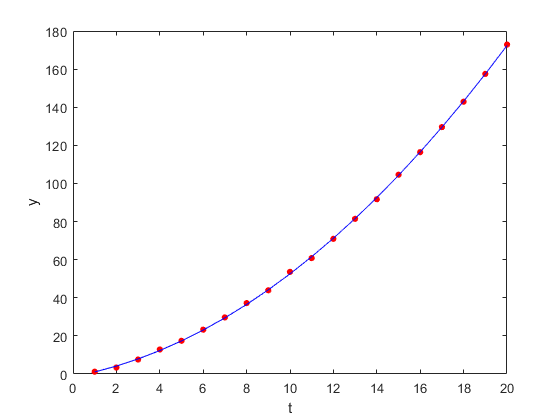

hold on, plot(t, A*c, 'b')

### A2. Nonlinear transformations

By a suitable transformation, sometimes nonlinear least squares problems can be converted to linear least squares problems.  Suppose we wish to determine how the runtime for finding all the eigenvalues of a symmetric matrix in MATLAB scales with the dimension $N$.  It's reasonable to assume that for sufficiently large $N$, this runtime takes the form of a power law:


$$\textrm{runtime} = A\, N^\alpha$$


for some unknowns $A$ and $\alpha$.  Taking logs, we have


$$\log(\textrm{runtime}) = \log(A) + \, \alpha\, \log(N) = B + \alpha \log(N)$$


which is now linear in $B\ ( = \log(A)\, )$ and $\alpha$.

We will gather some runtime data for a sequence of random symmetric matrices of dimensions $1000, 1100, 1200, \ldots, 2000$.

N = 2000:100:3000  % I upped the dimensions a bit here

N =         2000        2100        2200        2300        2400        2500        2600        2700        2800        2900        3000


runtime = zeros(size(N));
for i = 1:length(N)
    A = rand(N(i)); A = (A+A')/2; % symmetric
    tic
    eig(A);
    runtime(i) = toc;
end
runtime

runtime =     0.2499    0.2637    0.2979    0.3156    0.3633    0.3886    0.4386    0.4729    0.5281    0.5972    0.6574


Plot the data points $(N_i,\ \textrm{runtime}_i)$ on a new figure.

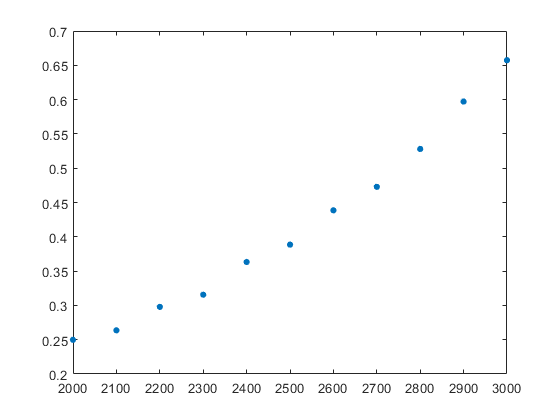

figure, plot(N, runtime, '.', 'markersize', 16)

In fact, given our proposed scaling law, it would make sense to use a *log-log* figure to display the data.  Try it this way now and confirm the data appear to lie on a straightish-looking line.

figure, loglog(N, runtime, '.', 'markersize', 16)

Form the linear least squares problem to solve for the unknowns, and report the fitted values of $A$ and $\alpha$.  According to your findings, how does the runtime scale with $N$?

A = log(N)'.^(0:1), c = A \ log(runtime)'

A =     1.0000    7.6009
    1.0000    7.6497
    1.0000    7.6962
    1.0000    7.7407
    1.0000    7.7832
    1.0000    7.8240
    1.0000    7.8633
    1.0000    7.9010
    1.0000    7.9374
    1.0000    7.9725


c =   -19.8637
    2.4229


Plot the fitted line over the data, to confirm visually how well it fits.

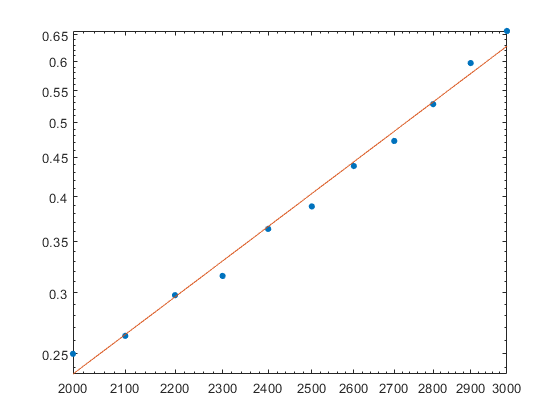

hold on, plot(N, exp(c(1)) * N.^c(2))

It's coming out as around O(N^2.5).  The data do seem to lie on the line to within experimental variation.

What would be possible sources of error in this analysis?  How could you mitigate these?

The dimensions are still small, so we might not be large enough to ignore lower order terms in the Big O complexity.  Runtime is also affected by other things like data transfer.

## Software

### S1. Linear Solver

Modify your MATLAB function `linear_solve` from Exercises 1 that takes as input an $m\times n$ symbolic matrix $A$ and $n \times 1$ right hand side vector $b$, and returns the solution $x$ to $Ax = b$.  It should:

- output a **warning **message if there is no solution, and instead return the *least squares solution* $x = \textrm{argmin}_{x^* \in \mathbb{R}^n} \|b - Ax^*\|$

- otherwise behave the same as in Exercises 1

Test your function out on various examples to check it handles all the different cases correctly.

Check out `linear_solve2.m`